# Explainable AI for Medical Images 

In this example, we show how to use MATLAB to produce post-hoc explanations (using [Grad-CAM](https://www.mathworks.com/help/deeplearning/ref/gradcam.html) and [image LIME](https://www.mathworks.com/help/deeplearning/ref/imagelime.html)) for a medical image classification task, defined as follows: 

**Given a chest x-ray (CXR), our solution should **[**classify it into Posteroanterior (PA) or Lateral (L) view**](https://doi.org/10.1016/j.media.2020.101797)**.  **

The dataset (PadChest) can be downloaded from [https://bimcv.cipf.es/bimcv-projects/padchest/](https://bimcv.cipf.es/bimcv-projects/padchest/) .

Both methods ([`gradCAM`](matlab:doc('gradCAM')) and [`imageLIME`](matlab:doc('imageLIME'))) are available as part of the MATLAB Deep Learning toolbox and require a single line of code to be applied to results of predictions made by a deep neural network (plus a few lines of code to display the results as a colormap overlaid on the actual images).

### Load training data

% Please adjust the path below, if needed
dataFolder = 'PneumoniaDataset';

imdsTrain = imageDatastore(dataFolder, ...
    'IncludeSubfolders',true, ....
    'LabelSource','foldernames');

numTrainingFiles = 0.7;
[imdsTrain,imdsValidation] = splitEachLabel(imdsTrain,numTrainingFiles);

rng(42); % Random number generator seed (to ensure reproducibility)


### Display example images

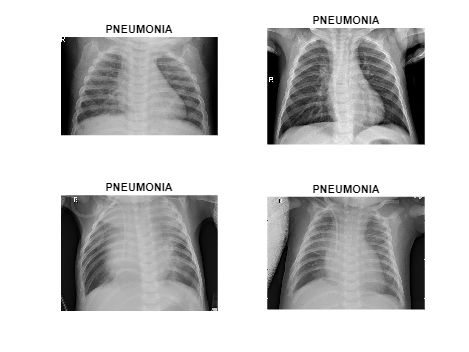

numTrainImages = numel(imdsTrain.Labels);
idx = randperm(numTrainImages,4);
figure
for i = 1:4
    subplot(2,2,i)
    I = readimage(imdsTrain,idx(i));
    imshow(I), title(imdsTrain.Labels(idx(i)))
end

### Define network and data augmentation options

imageAugmenter = imageDataAugmenter( ...
    'RandXTranslation',[-3 3], ...
'RandYTranslation',[-3 3]);
net = resnet50;
lgraph = layerGraph(net);
clear net;
%layers = layerGraph(net);
%inputSize = net.Layers(1).InputSize;


 % Number of categories
    numClasses = numel(categories(imdsTrain.Labels));

 %   imdsTrainAug = augmentedImageDatastore(inputSize(1:2),imdsTrain, ...
 %   'DataAugmentation', imageAugmenter);
%imdsValidationAug = augmentedImageDatastore(inputSize(1:2), ...
%   imdsValidation);
    
    % New Learnable Layer
    newLearnableLayer = fullyConnectedLayer(numClasses, ...
        'Name','new_fc', ...
        'WeightLearnRateFactor',10, ...
        'BiasLearnRateFactor',10);
    
    % Replacing the last layers with new layers
    lgraph = replaceLayer(lgraph,'fc1000',newLearnableLayer);
    newsoftmaxLayer = softmaxLayer('Name','new_softmax');
    lgraph = replaceLayer(lgraph,'fc1000_softmax',newsoftmaxLayer);
    newClassLayer = classificationLayer('Name','new_classoutput');
    lgraph = replaceLayer(lgraph,'ClassificationLayer_fc1000',newClassLayer);
    
    
    % Preprocessing Technique
    imdsTrain.ReadFcn = @(filename)preprocess_Xray(filename);
    imdsTest.ReadFcn = @(filename)preprocess_Xray(filename);
    imdsValidation.ReadFcn = @(filename)preprocess_Xray(filename);
    
 
    
    % Data Augumentation
    augmenter = imageDataAugmenter( ...
        'RandRotation',[-5 5],'RandXReflection',1,...
        'RandYReflection',1,'RandXShear',[-0.05 0.05],'RandYShear',[-0.05 0.05]);
    
    % Resizing all training images to [224 224] for ResNet architecture
    auimds = augmentedImageDatastore([224 224],imdsTrain,'DataAugmentation',augmenter);
    imdsValidationAug = augmentedImageDatastore([224 224],imdsValidation,'DataAugmentation',augmenter);
   

%newClassLayer = classificationLayer('Name','new_classoutput');
%layers = replaceLayer(layers,'ClassificationLayer_predictions',newClassLayer);

### Specify training options

    options = trainingOptions('adam',...
        'MaxEpochs',30,'MiniBatchSize',8,...
        'Shuffle','every-epoch', ...
        'InitialLearnRate',1e-4, ...
        'Verbose',false, ...
        'Plots','training-progress');


### Train network

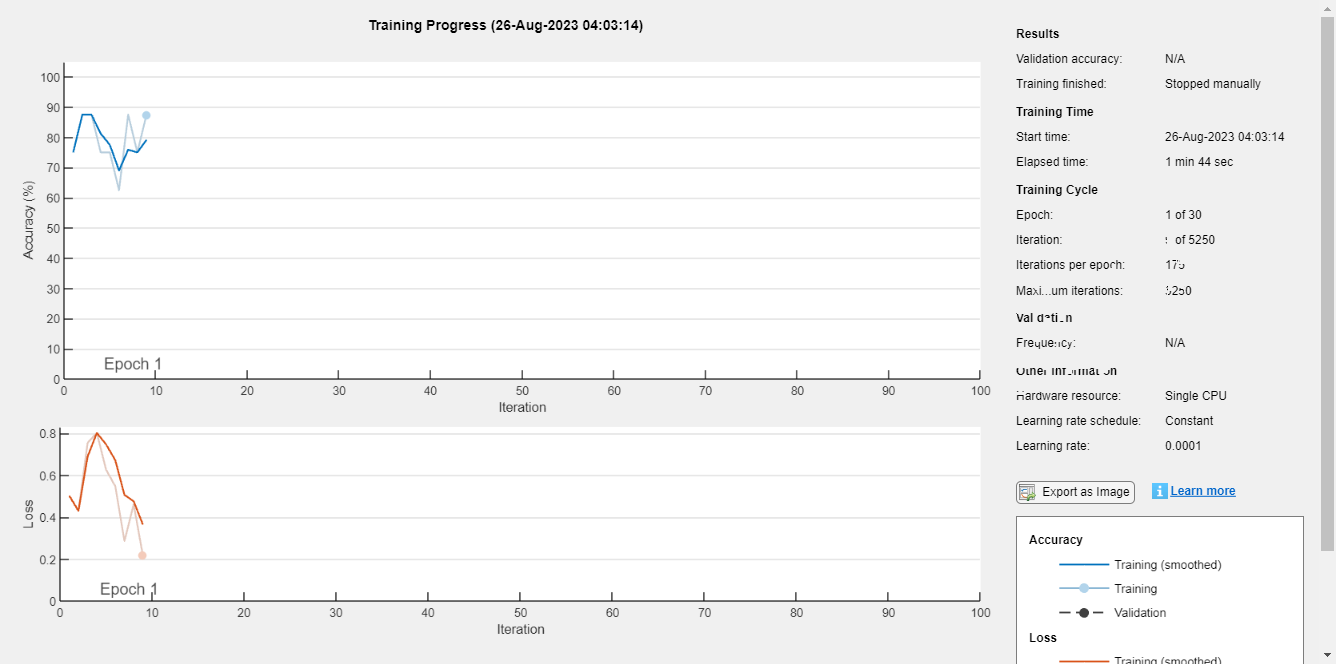

netTransfer = trainNetwork(imdsValidationAug,lgraph,options);

### Classify validation Images

Classify the validation images using the fine-tuned network.

[YPred,scores] = classify(netTransfer,imdsValidationAug);
YValidation = imdsValidation.Labels;

Display four sample validation images with their predicted labels.

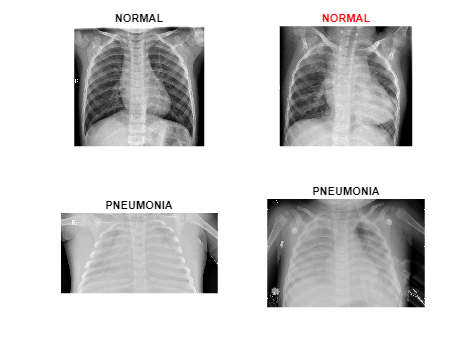

idx = randperm(numel(imdsValidation.Files),4);
figure
for i = 1:4
    subplot(2,2,i)
    I = readimage(imdsValidation,idx(i));
    imshow(I)
    label = YPred(idx(i));
    if(YPred(idx(i)) == YValidation(idx(i)))
        title(string(label), 'Color','black');
    else
        title(string(label), 'Color','red');
    end
end

Calculate the classification accuracy on the validation set. Accuracy is the fraction of labels that the network predicts correctly.

YValidation = imdsValidation.Labels;
accuracy = mean(YPred == YValidation)

accuracy = 0.7701

### Explain predictions

#### Using `gradCAM`

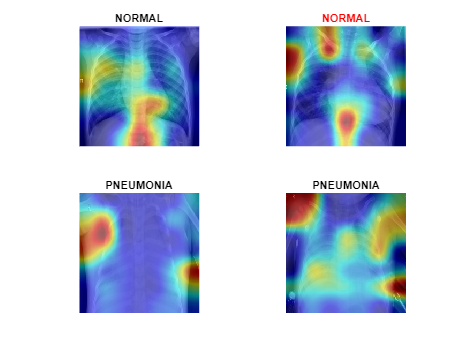

figure
for i = 1:4
    subplot(2,2,i)
    I = readimage(imdsValidation,idx(i));
    I_resized = imresize(I,netTransfer.Layers(1).InputSize(1:2));
    label = YPred(idx(i));
    % scoreMap = gradCAM(netTransfer,I_resized,label);
    scoreMap = gradCAM(netTransfer,I_resized,label);
    % imshow(I_resized)
    imshow(I_resized)
    hold on
    imagesc(scoreMap,'AlphaData',0.5)
    colormap jet
    if(YPred(idx(i)) == YValidation(idx(i)))
        title(string(label), 'Color','black');
    else
        title(string(label), 'Color','red');
    end
    hold off
end

#### Using `imageLIME`

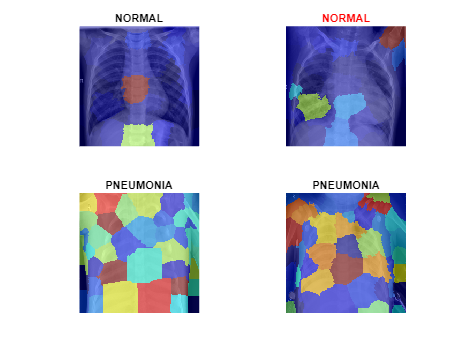

figure
for i = 1:4
    subplot(2,2,i)
    I = readimage(imdsValidation,idx(i));
    I_resized = imresize(I,netTransfer.Layers(1).InputSize(1:2));
    label = YPred(idx(i));
    scoreMap = imageLIME(netTransfer,I_resized,label);
    imshow(I_resized)
    hold on
    imagesc(scoreMap,'AlphaData',0.5)
    colormap jet
    % colorbar
    if(YPred(idx(i)) == YValidation(idx(i)))
        title(string(label), 'Color','black');
    else
        title(string(label), 'Color','red');
    end
    hold off
end

function Iout = preprocess_Xray(filename)
% Read the Filename
I = imread(filename);
% Some images might be RGB, convert them to Grayscale
if ~ismatrix(I)
    I=rgb2gray(I); 
end
% Replicate the image 3 times to create an RGB image
Iout = cat(3,I,I,I);
end